# **RS-WISP-04-03 CircumNavigation**

**WorkerInSpace**

**Hongseok Kim**

**2/6/2025**

## **I. Scope**

  It can be shown that the initial velocity components that a chaser must have to initiate an elliptic, natural flyaround at any location $\left(x,z\right)$ are:


$$\begin{array}{l}
\dot{x} =\left(n/2\right)y\\
\dot{y} =-2\textrm{nx}
\end{array}$$


  Under ideal conditions, the chaser then will traverse the elliptic path, counterclockwise about the orbit normal $y$ axis:


$$\begin{array}{l}
x\left(t\right)=x_0 \;\cos \;\textrm{nt}+\frac{1}{2}y_0 \;\sin \;\textrm{nt}\\
y\left(t\right)=-2x_0 \;\sin \;\textrm{nt}+y_0 \;\cos \;\textrm{nt}
\end{array}$$


  where $\left(x_0 ,z_0 \right)$ is the initial location of the chaser at $t=0$. The maximum $x$ and $z$ components of the elliptic path are $x_{\max } =\frac{1}{2}y_{\max }$, $y_{\max } =\pm {\left(y_0^2 +x_0^2 \right)}^{1/2}$, which define the size of the flyaround.

## II. CircumNavigation Procedure

### II.1 I/O Structure


$$\begin{array}{l}
\textrm{Input}\;\textrm{Parameter}\\
\;-\textrm{Position}\;\textrm{and}\;\textrm{velocity}\;\textrm{of}\;\textrm{Taget}\;\textrm{Satellite}:r_{\textrm{target}} ={\mathit{\mathbf{r}}}_0 \;,v_{\textrm{target}} ={\mathit{\mathbf{v}}}_0 \\
\;-\textrm{Position}\;\textrm{and}\;\textrm{velocity}\;\textrm{of}\;\textrm{Chaser}\;\textrm{Satellite}:{\mathit{\mathbf{r}}}_{\textrm{chaser}} =\mathit{\mathbf{r}},{\mathit{\mathbf{v}}}_{\textrm{chaser}} =\mathit{\mathbf{v}}\\
\;-\textrm{Number}\;\textrm{of}\;\textrm{rotation}\;N\\
\;-\alpha \;\textrm{for}\;\textrm{modeling}\;\delta \dot{z} \\
\\
\textrm{Output}\;\textrm{Parameter}\\
\;\;-\delta \mathit{\mathbf{r}}\left(\mathit{\mathbf{t}}\right)\;\textrm{and}\;\delta \mathit{\mathbf{v}}\left(\mathit{\mathbf{t}}\right)\;\textrm{data}\;\textrm{with}\;\textrm{respect}\;\textrm{to}\;\textrm{LVLH}\;\textrm{frame}\\
\;-\textrm{initial}\;{\mathit{\mathbf{v}}}_{\textrm{ECI}}^+ \;\textrm{with}\;\textrm{respect}\;\textrm{to}\;\textrm{ECI}\;\textrm{frame}\;\textrm{for}\;\textrm{orbit}\;\textrm{propagation}\\
\;\;-\textrm{Total}\;\textrm{simulation}\;\textrm{time}\;T=N\times \frac{2\pi }{n}\\
\left(\textrm{Note}\;:\textrm{the}\;\textrm{actual}\;\textrm{path}\;\textrm{should}\;\textrm{be}\;\textrm{drawn}\;\textrm{in}\;\textrm{ECI}\;\textrm{frame}\;\textrm{for}\;\textrm{cross}\;\textrm{check}\right)
\end{array}$$


### II.2 CircumNavigation Algorithm


$$\begin{array}{l}
1\ldotp \textrm{Transformation}\;\textrm{matrix}\;\textrm{from}\;\textrm{ECI}\;\textrm{to}\;\textrm{Target}\;\textrm{LVLH}\;\textrm{frame}\\
\;\;\;\hat{\mathbf{i}} =\frac{{\mathit{\mathbf{r}}}_0 }{\left|{\mathit{\mathbf{r}}}_0 \right|},\;\hat{\mathbf{k}} =\frac{{\mathit{\mathbf{r}}}_0 \times {\mathit{\mathbf{v}}}_0 }{\left|{\mathit{\mathbf{r}}}_0 \times {\mathit{\mathbf{v}}}_0 \right|},\hat{\mathbf{j}} =\hat{\mathbf{k}} \times \hat{\mathbf{i}} \Rightarrow {\left\lbrack Q\right\rbrack }_{\textrm{LVLH},\textrm{ECI}} =\left\lbrack \begin{array}{ccc}
- & {\left\lbrack \hat{\mathbf{i}} \right\rbrack }^T  & -\\
- & {\left\lbrack \hat{\mathbf{j}} \right\rbrack }^T  & -\\
- & {\left\lbrack \hat{\mathbf{k}} \right\rbrack }^T  & -
\end{array}\right\rbrack \\
\\
2\ldotp \textrm{Calculate}\;\textrm{mean}\;\textrm{motion}\;\textrm{of}\;\textrm{Target}\;\textrm{and}\;\textrm{corresponding}\;\textrm{angular}\;\textrm{veocity}\\
\;\;\textrm{mean}\;\textrm{motion}\;\textrm{of}\;\textrm{Target}\;n=\frac{v_0 }{r_0 }\\
\;\;\Omega_{\textrm{Target}} =n\hat{\mathbf{k}} \\

\end{array}$$



$$\begin{array}{l}
3\ldotp \textrm{Calculate}\;\textrm{initial}\;\textrm{relative}\;\textrm{position}\;\textrm{and}\;\textrm{velocity}\;\textrm{vector}\;\textrm{of}\;\textrm{the}\;\textrm{Chaser}\;\textrm{wrt}\;\textrm{ECI}\;\textrm{frame}\\
\;\;{\mathit{\mathbf{r}}}_{\textrm{rel}} =\delta \mathit{\mathbf{r}},{\mathit{\mathbf{v}}}_{\textrm{rel}} =\delta \mathit{\mathbf{v}}\\
\;\;\mathit{\mathbf{v}}={\mathit{\mathbf{v}}}_0 +\Omega_{\textrm{Target}} \times {\mathit{\mathbf{r}}}_{\textrm{rel}} +{\mathit{\mathbf{v}}}_{\textrm{rel}} \\
\;\;\delta \mathit{\mathbf{r}}=\mathit{\mathbf{r}}-{\mathit{\mathbf{r}}}_0 \\
\;\;\delta \mathit{\mathbf{v}}=\mathit{\mathbf{v}}-{\mathit{\mathbf{v}}}_0 -\Omega_{\textrm{Target}} \times \delta \mathit{\mathbf{r}}\\
\\
4\ldotp \textrm{Calculate}\;\textrm{initial}\;\textrm{reletive}\;\textrm{position}\;\textrm{and}\;\textrm{velocity}\;\textrm{vector}\;\textrm{of}\;\textrm{the}\;\textrm{Chaser}\;\textrm{wrt}\;\textrm{Target}\;\textrm{LVLH}\;\textrm{frame}\\
\;\;{\left\lbrack \delta {\mathit{\mathbf{r}}}_0 \right\rbrack }_{\textrm{LVLH}} ={\left\lbrack Q\right\rbrack }_{\textrm{LVLH},\textrm{ECI}} \;\delta \mathit{\mathbf{r}}\\
\;\;{\left\lbrack \delta {\mathit{\mathbf{v}}}_0^- \right\rbrack }_{\textrm{LVLH}} ={\left\lbrack Q\right\rbrack }_{\textrm{LVLH},\textrm{ECI}} \;\delta \mathit{\mathbf{v}}\;\;\\

\end{array}$$



$$\begin{array}{l}
5\ldotp \textrm{Generate}\;\textrm{Clohessy}-\textrm{Wiltshire}\;\textrm{matrices}\;\textrm{function}\;\textrm{for}\;\textrm{given}\;\textrm{mean}\;\textrm{motion}\\
\;\;\left\lbrack \Phi_{\textrm{rr}} \left(t\right)\right\rbrack =\left\lbrack \begin{array}{ccc}
4-3\cos \;\textrm{nt} & 0 & 0\\
6\left(\;\sin \;\textrm{nt}-\textrm{nt}\right) & 1 & 0\\
0 & 0 & \cos \;\textrm{nt}
\end{array}\right\rbrack \;\;\;\left\lbrack \Phi_{\textrm{rv}} \left(t\right)\right\rbrack =\left\lbrack \begin{array}{ccc}
\frac{\sin \;\textrm{nt}}{n} & \frac{2}{n}\left(1-\cos \;\textrm{nt}\right) & 0\\
\frac{2}{n}\left(\cos \;\textrm{nt}-1\right) & \frac{4}{n}\sin \;\textrm{nt}-3t & 0\\
0 & 0 & \frac{1}{n}\sin \;\textrm{nt}
\end{array}\right\rbrack \\
\;\;\left\lbrack \Phi_{\textrm{vr}} \left(t\right)\right\rbrack =\left\lbrack \begin{array}{ccc}
3n\;\sin \;\textrm{nt} & 0 & 0\\
6n\left(\cos \;\textrm{nt}-1\right) & 0 & 0\\
0 & 0 & -n\;\sin \;\textrm{nt}
\end{array}\right\rbrack \;\;\left\lbrack \Phi_{\textrm{vv}} \left(t\right)\right\rbrack =\left\lbrack \begin{array}{ccc}
\cos \;\textrm{nt} & 2\;\sin \;\textrm{nt} & 0\\
-2\;\sin \;\textrm{nt} & 4\cos \;\textrm{nt}-3 & 0\\
0 & 0 & \cos \;\textrm{nt}
\end{array}\right\rbrack \\

\end{array}$$



$$\begin{array}{l}
6\ldotp \textrm{From}\;\textrm{given}\;\left\lbrack \delta {\mathit{\mathbf{r}}}_0 \right\rbrack ,\textrm{find}\;\left\lbrack \delta {\mathit{\mathbf{v}}}_0^+ \right\rbrack \;\textrm{and}\;\textrm{corresponding}\;\left\lbrack \Delta {\mathit{\mathbf{v}}}_0 \right\rbrack \;\textrm{wrt}\;\textrm{LVLH}\;\textrm{frame}\\
\;\;\;\;\left\lbrack \delta {\mathit{\mathbf{v}}}_0^+ \right\rbrack =\left\lbrack \begin{array}{ccc}
0 & n/2 & 0\\
-2n & 0 & 0\\
0 & 0 & \alpha 
\end{array}\right\rbrack \;\left\lbrack \delta {\mathit{\mathbf{r}}}_0 \right\rbrack \\
\;\;\;\;{\left\lbrack \Delta {\mathit{\mathbf{v}}}_0 \right\rbrack }_{\textrm{LVLH}} =\left\lbrack \delta {\mathit{\mathbf{v}}}_0^+ \right\rbrack -\left\lbrack \delta {\mathit{\mathbf{v}}}_0^- \right\rbrack \\
\\
7\ldotp \textrm{Calculate}\;\textrm{the}\;\textrm{total}\;\textrm{simulate}\;\textrm{time}\;T=N\times \frac{2\pi }{n}\;\textrm{and}\;\textrm{propagate},\textrm{get}\;{\left\lbrack \delta \mathit{\mathbf{r}}\right\rbrack }_{\textrm{LVLH}} \;\textrm{and}\;{\left\lbrack \delta \mathit{\mathbf{v}}\right\rbrack }_{\textrm{LVLH}} \\
\;\;\left\lbrack \delta \mathit{\mathbf{r}}\left(t\right)\right\rbrack =\left\lbrack \Phi_{\textrm{rr}} \left(t\right)\right\rbrack \left\lbrack \delta {\mathit{\mathbf{r}}}_0 \right\rbrack +\left\lbrack \Phi_{\textrm{rv}} \left(t\right)\right\rbrack \left\lbrack \delta {\mathit{\mathbf{v}}}_0 \right\rbrack \\
\;\;\left\lbrack \delta \mathit{\mathbf{v}}\left(t\right)\right\rbrack =\left\lbrack \Phi_{\textrm{vr}} \left(t\right)\right\rbrack \left\lbrack \delta {\mathit{\mathbf{r}}}_0 \right\rbrack +\left\lbrack \Phi_{\textrm{vv}} \left(t\right)\right\rbrack \left\lbrack \delta {\mathit{\mathbf{v}}}_0 \right\rbrack \\

\end{array}$$



$$\begin{array}{l}
8\ldotp \textrm{From}\;\textrm{LVLH}\;\textrm{to}\;\textrm{ECI}\;\textrm{coordinate}\;\textrm{transfer},\textrm{we}\;\textrm{can}\;\textrm{calculate}\;{\mathit{\mathbf{v}}}_{\textrm{ECI}}^+ \;\textrm{from}\;\left\lbrack \delta {\mathit{\mathbf{v}}}_0^+ \right\rbrack \\
\;\;\textrm{from}\;\mathit{\mathbf{v}}={\mathit{\mathbf{v}}}_0 +\Omega_{\textrm{Target}} \times {\mathit{\mathbf{r}}}_{\textrm{rel}} +{\mathit{\mathbf{v}}}_{\textrm{rel}} \\
\;\;{\mathit{\mathbf{v}}}_{\textrm{ECI}}^+ ={\mathit{\mathbf{v}}}_0 +\Omega_{\textrm{Target}} \times \delta \mathit{\mathbf{r}}+{\left\lbrack \mathit{\mathbf{Q}}\right\rbrack }_{\textrm{LVLH},\textrm{ECI}}^{-1} \left\lbrack \delta {\mathit{\mathbf{v}}}_0^+ \right\rbrack \\
\;\;\left(\textrm{note}:{\mathit{\mathbf{v}}}_0 ={\textrm{Target}}^{\prime } s\;\textrm{veclotiy}\;\textrm{wrt}\;\textrm{ECI},\;\left\lbrack \delta {\mathit{\mathbf{v}}}_0^+ \right\rbrack ={\textrm{Chaser}}^{\prime } s\;\textrm{relative}\;\textrm{velocity}\;\textrm{wrt}\;{\textrm{target}}^{\prime } s\;\textrm{LVLH}\right)
\end{array}$$


## IV. Matlab function demonstration

function [Delta_v_0, delta_r_t_mat, delta_v_t_mat, v_plus_ECI, tf] = cirumNavigation(r_target, v_target, r_chaser, v_chaser, N, alpha)

r_0 = r_target;
v_0 = v_target;
r = r_chaser;
v = v_chaser;

% Reference Frame of the Target
i_hat = r_0/norm(r_0);
j_hat = v_0/norm(v_0);
k_hat = cross(i_hat, j_hat);

% Transformation Matrix from ECI to Space Station Frame
Q_LVLH_ECI = [i_hat';j_hat';k_hat'];

% Position vector of the spacecraft relative to the space station (ECI)
delta_r = r - r_0;
n = norm(v_0)/norm(r_0);
Omega_target = n * k_hat;
delta_v = v - v_0 - cross(Omega_target, delta_r);

% Relative position vector at the beginning of the rendezvous maneuver
delta_r_0 = Q_LVLH_ECI * delta_r;

% Relative velocity just before launch into the rendezvous trajectory is
delta_v_0_minus = Q_LVLH_ECI * delta_v;

tf = N * 2* pi / n;

delta_v_0_plus = [0, n/2, 0;
                  -2*n, 0, 0;
                  0, 0, 0] * delta_r_0;

% Delta-v at the beginning of the rendezvous maneuver
Delta_v_0 = delta_v_0_plus - delta_v_0_minus;


% Drawing Reference Chaser Trajector wrt Target
t_vector = linspace(0,tf);
delta_r_t_mat = zeros(length(t_vector),3);
delta_v_t_mat = zeros(length(t_vector),3);

for timestep = 1:length(t_vector)

    t = t_vector(timestep);

    nt = n*t;

    Phi_rr_t = [4 - 3*cos(nt),   0, 0;
              6*(sin(nt) - nt),1,0;
              0,0, cos(nt)];
    
    Phi_rv_t = [sin(nt)/n, 2/n * (1 - cos(nt)), 0;
              2/n*(cos(nt)-1), 4/n*sin(nt)-3*t,0;
              0,0,1/n*sin(nt)];
    
    Phi_vr_t = [3*n*sin(nt),0,0;
              6*n*(cos(nt)-1),0,0;
              0,0,-n*sin(nt)];
    Phi_vv_t = [cos(nt), 2*sin(nt),0
             -2*sin(nt), 4*cos(nt)-3, 0;
              0,0,cos(nt)];

    delta_r_t = Phi_rr_t * delta_r_0 + Phi_rv_t * delta_v_0_plus;
    delta_v_t = Phi_vr_t * delta_r_0 +  Phi_vv_t * delta_v_0_plus;

    delta_r_t_mat(timestep,:) = delta_r_t';
    delta_v_t_mat(timestep,:) = delta_v_t';
end

v_plus_ECI = v_0 + cross(Omega_target, delta_r) + inv(Q_LVLH_ECI) * delta_v_0_plus;

end

## IV. Matlab Function Test

%% Input Parameters

% Target Information
Target.a = 300+6378;
Target.e = 1e-5;
Target.i = 40;
Target.RAAN = 20;
Target.AOP = 0;
Target.TA = 60;


% Chaser Information
Chaser.a = 6378 + (318.5 + 515.51)/2;
Chaser.e = (6378+515.51)/Chaser.a-1;
Chaser.i = 40.130;
Chaser.RAAN = 19.819;
Chaser.AOP = 70.662;
Chaser.TA = 349.65;

% Timing of Docking
t_f = 28800;

%% Main Algorithm

% Change to ECI frame

% rv data of the target wrt ECI
[r_target, v_target] = kepler2ijk_hs(Target.a, Target.e, Target.i, Target.RAAN, Target.AOP, Target.TA);

% rc data of the chaser wrt ECI
[r_chaser, v_chaser] = kepler2ijk_hs(Chaser.a, Chaser.e, Chaser.i, Chaser.RAAN, Chaser.AOP, Chaser.TA);

N = 5;
alpha = 1;

[Delta_v_0, delta_r_t_mat, delta_v_t_mat, v_plus_ECI, tf] = cirumNavigation(r_target, v_target, r_chaser, v_chaser, N, alpha);

### IV.1 Data Display

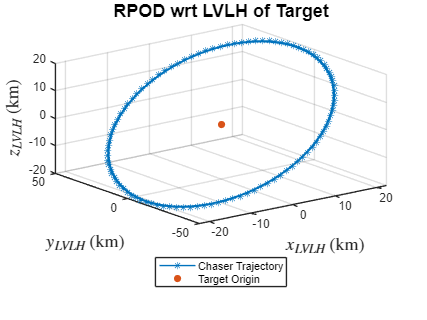

figure;
plot3(delta_r_t_mat(:,1),delta_r_t_mat(:,2),delta_r_t_mat(:,3),'*-')
hold on
scatter3(0,0,0,'filled','o')
hold off
grid on
title('RPOD wrt LVLH of Target','FontSize',15,'FontWeight','bold')
xlabel('$x_{LVLH}$ (km)', 'Interpreter', 'latex','FontSize',15)
ylabel('$y_{LVLH}$ (km)', 'Interpreter', 'latex','FontSize',15)
zlabel('$z_{LVLH}$ (km)', 'Interpreter', 'latex','FontSize',15)
legend('Chaser Trajectory', 'Target Origin','Location','southoutside')

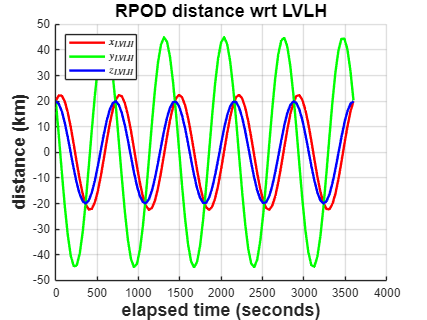



figure;
hold on
plot(t_vector, delta_r_t_mat(:,1),'r','LineWidth',2)
plot(t_vector, delta_r_t_mat(:,2),'g','LineWidth',2)
plot(t_vector, delta_r_t_mat(:,3),'b','LineWidth',2)
hold off
title('RPOD distance wrt LVLH','FontSize',15,'FontWeight','bold')
xlabel('elapsed time (seconds)','FontSize',15,'FontWeight','bold')
ylabel('distance (km)','FontSize',15,'FontWeight','bold')
legend('$x_{LVLH}$','$y_{LVLH}$','$z_{LVLH}$', 'Interpreter', 'latex','Location','northwest')
grid on


tVec = 1:1:tf;
n = length(tVec);

% Propaget Target and Chaser under 2-body dynamics
[t,y_chaser] = orbit_propagation(r_chaser, v_plus_ECI, tVec);
[t,y_target] = orbit_propagation(r_target, v_target, tVec);

y_chaser(end,:)

ans = 1.0e+03 *

    1.6307    5.3090    3.7442   -0.0073    0.0005    0.0025


y_target(end,:)

ans = 1.0e+03 *

    1.6373    5.3041    3.7123   -0.0073    0.0005    0.0025


y_chaser(end,1:3) - y_target(end,1:3)

ans =    -6.6113    4.9468   31.8446


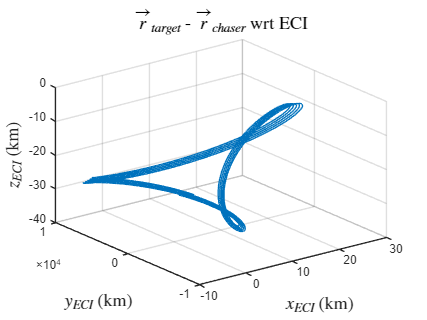


figure;
plot3(y_target(:,1)-y_chaser(:,1),y_target(:,2)-y_chaser(:,1),y_target(:,3)-y_chaser(:,3))

grid on
title('$\vec r_{target}$ - $\vec r_{chaser}$ wrt ECI', 'Interpreter', 'latex','FontSize',15)
xlabel('$x_{ECI}$ (km)', 'Interpreter', 'latex','FontSize',15)
ylabel('$y_{ECI}$ (km)', 'Interpreter', 'latex','FontSize',15)
zlabel('$z_{ECI}$ (km)', 'Interpreter', 'latex','FontSize',15)

## Appendix 1: Bundle functions (kepler2ijk, ijk2kepler)

function [r,v] = kepler2ijk_hs(a,e,inc,RAAN,AOP,theta)

mu = 398600.4415;

RAAN = RAAN/180*pi;
inc = inc/180*pi;
AOP = AOP/180*pi;
theta = theta/180*pi;


R_3_AOP = [cos(AOP), sin(AOP),0;
           -sin(AOP), cos(AOP),0;
                    0,       0,1];

R_1_inc = [1,       0,         0;
           0, cos(inc),  sin(inc);
           0,-sin(inc),  cos(inc)];

R_3_RAAN = [cos(RAAN), sin(RAAN),0;
           -sin(RAAN), cos(RAAN),0;
                    0,       0,1];


Q_rotation = R_3_AOP * R_1_inc * R_3_RAAN;

p = Q_rotation(1,:);
q = Q_rotation(2,:);
w = Q_rotation(3,:);

p_value = a*(1-e^2);
r = p_value* (cos(theta)*p + sin(theta) *q)/(1+e*cos(theta));
r = r';
v = sqrt(mu/p_value)*(-sin(theta)*p+(e+cos(theta))*q)';
end


function [a, e, inc, RAAN, AOP, theta] = ijk2kepler_hs(r,v)

mu = 398600.4415;

h = cross(r,v);                                   % Angular Velocity Vector
z = [0,0,1]';
n = (cross(z,h))/(norm(cross(z,h)));              % Normal Vector
e_vector = ((cross(v,h))/mu) - r/(norm(r));       % Eccentricity vector


a = (-mu)/((norm(v))^2 - 2*mu/norm(r));           % 1. Semi-major axis
e = norm(e_vector);                               % 2. Eccentricity
inc = acos(dot(z,h)/norm(h)) / pi *180;           % 3. Inclination

RAAN = atan2(n(2),n(1));                          % 4. RAAN
RAAN = RAAN / pi * 180;

AOP = acos((dot(n,e_vector))/norm(e_vector));                   % 5. Argument of periapse
if(e_vector(3)<0)
    AOP = 2*pi - AOP;
end
AOP = AOP/pi*180;

theta = acos((dot(r,e_vector))/(norm(r)*norm(e_vector)));       % 6. True anomaly
if(dot(r,v) < 0)
    theta = 2*pi-theta;
end
theta = theta / pi * 180;

end

## Appendix 3: 2-body orbit propagator in ECI

function dydt = two_body_dynamics(t,y)

 % Define the standard gravitational parameter for Earth (km^3/s^2)
    mu = 398600.4415;
 
 % Extract position and velocity from the input state vector
    r_vec = y(1:3); % Position vector
    v_vec = y(4:6); % Velocity vector

 % Calculate the norm of the position vector
    r_norm = norm(r_vec);

 % Compute the acceleration based on the gravitational force
   a1 = -mu*r_vec(1)/(r_norm^3);
   a2 = -mu*r_vec(2)/(r_norm^3);
   a3 = -mu*r_vec(3)/(r_norm^3);

 % Combine velocity and acceleration to form the derivative of the state vector
    dydt = [v_vec; a1;a2;a3];
end



function [t,y] = orbit_propagation(r0, v0, tVec)

    odeoptions = odeset('RelTol',1e-10,'AbsTo',1e-20);
    % Calculate the magnitude of the position and velocity vectors
    y0 = [r0;v0];
    
    % Solve the ODE using ode45
    [t, y] = ode45(@two_body_dynamics, tVec, y0, odeoptions);
end
